    16



    16



   579



        4492



       82621




acCoeffs =

     []



    0.0557



    16



    16



        1357



        5853



      136622




acCoeffs =

     []



    0.0432



    16



    16



        2236



        6817



      174524




acCoeffs =

     []



    0.0399



    16



    16



        2925



        7367



      205383




acCoeffs =

     []



    0.0382



    16



    16



        3598



        7833



      231483




acCoeffs =

     []



    0.0372



    16



    16



        4381



        8336



      254259




acCoeffs =

     []



    0.0366



    16



    16



        4876



        8481



      274943




acCoeffs =

     []



    0.0363



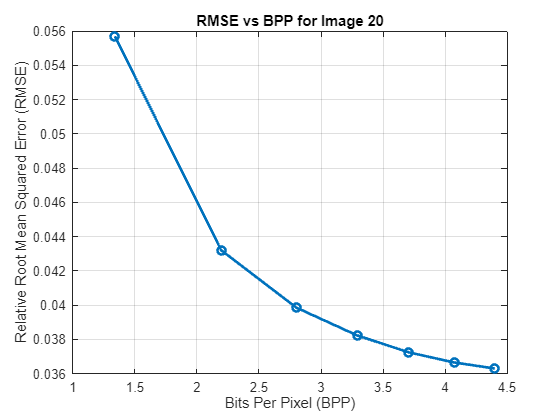

Q = 10:15:100; % Quality factors
num_quality_factors = length(Q); % Number of quality factors
image_files = dir('bw/*.png'); % Get all .jpg files in the current folder
text_files = dir('output/*.txt'); % Get all .txt files in the current folder
num_images = length(image_files); % Number of images

% Preallocate RMSE and BPP matrices
RMSE = zeros(num_images, num_quality_factors);
BPP = zeros(num_images, num_quality_factors);

% Check if the number of image and text files match


% Loop through each image
for a = 21:21

    clearvars -except a image_files num_images quality num_quality_factors text_files RMSE BPP;
    % Read the image
    filename= sprintf('rmse/%d.tiff', a);
    img = imread(filename);
    [height2, width2] = size(img); % Get image dimensions
    num_pixels = height2 * width2; % Total number of pixels in the image
for b = 1:7
    % Read the corresponding text file (binary strings or encoded data)
    filename = sprintf('output/example_a%d_b%d.txt', a, b);
    binaryStrings = readlines(filename);
    % Process RMSE and BPP for each quality factor (placeholder for actual logic)
  
disp(length(char(binaryStrings(1))))
disp(length(char(binaryStrings(2))))
disp(length(char(binaryStrings(3))))
disp(length(char(binaryStrings(4))))
disp(length(char(binaryStrings(5))))

    %for j = 1:num_quality_factors
        %decoded_image = decode_jpeg(encoded_image);
        %Decoding code:
% Read all lines as a string array

% Initialize an empty cell array to store decoded values
decodedTable = {};
encodedString = char(binaryStrings(3));

% Process each entry from the Huffman string
i = 1; % Initialize index
while i < length(encodedString)

    % Extract the 4-bit number of bits required for the number
    numBitsRequiredBin = encodedString(i:i+3);
    numBitsRequired = bin2dec(numBitsRequiredBin); % Convert to decimal
    i = i + 4;
    
    % Extract the number itself (the next numBitsRequired bits)
    numBin = encodedString(i:i+numBitsRequired);
    signBit = numBin(numBitsRequired);  
    magnitudeBinary = numBin(1:numBitsRequired-1);  % All except the last bit
    
    % Convert the magnitude part from binary to integer
    magnitude = bin2dec(magnitudeBinary);  % Convert binary to decimal (positive magnitude)
    
    % Apply the sign
    if signBit == '1'
        result = -magnitude;  % Negative number
    else
        result = magnitude;   % Positive number
    end
    i = i + numBitsRequired;
    
    % Extract the 6-bit number of bits in the Huffman code
    numBitsHuffmanBin = encodedString(i:i+5);
    numBitsHuffman = bin2dec(numBitsHuffmanBin); % Convert to decimal
    i = i + 6;
    
    % Extract the Huffman code (the next numBitsHuffman bits)
    huffmanCodeBin = encodedString(i:i+numBitsHuffman-1);
    i = i + numBitsHuffman;
    
    % Store the decoded entry in the table
    decodedTable{end+1} = {numBitsRequired, result, numBitsHuffman, huffmanCodeBin};
end
tableArray = cell2table(decodedTable');

dict = decodedTable';
encodedDc = char(binaryStrings(4));
decodedCoeffs = [];  % Array to store decoded coefficients

i = 1;  % Index to traverse the encoded binary string

% Initialize variables
i = 1;  % Index for navigating the encodedDc string
decodedDcCoeffs = [];  % Array to store the decoded DC coefficients
previousDc = 0;  % Initialize the previous DC coefficient (first block starts at 0)

% Decode the Huffman encoded DC coefficients
while i <= length(encodedDc)
    % Try to match a Huffman code from the dict
    foundMatch = false;  % Flag to check if a match was found
    for j = 1:length(dict)
        huffmanCode = dict{j}{4};  % Get the Huffman code from dict
        codeLength = length(huffmanCode);
        
        % Check if the next part of the string matches the Huffman code
        if i + codeLength - 1 <= length(encodedDc) && strcmp(encodedDc(i:i + codeLength - 1), huffmanCode)
            % Decode the difference value (symbol) from the dictionary
            diff = dict{j}{2};  % Get the difference value
            
            % Calculate the actual DC coefficient using the difference
            currentDc = previousDc + diff;
            decodedDcCoeffs = [decodedDcCoeffs, currentDc];  % Append the actual DC coefficient
            
            % Update the previous DC coefficient for the next block
            previousDc = currentDc;
            
            % Move the index forward by the length of the matched Huffman code
            i = i + codeLength;
            
            foundMatch = true;
            break;
        end
    end
    
    % If no match was found (which should not happen in theory), throw an error
    if ~foundMatch
        error('Huffman code mismatch at position %d', i);
    end
end


decodedCoeffs = decodedDcCoeffs;


encodedAc = char(binaryStrings(5));
decodedAc = []; % Initialize an array for storing the decoded AC coefficients
i = 1;          % Index for traversing the encodedAc binary string

while i <= length(encodedAc)
    % Extract the runlength (4 bits)
    runlength = bin2dec(encodedAc(i:i+3));
    i = i + 4;
    
    % Extract the size of the Huffman code (4 bits)
    huffLength = bin2dec(encodedAc(i:i+5));
    i = i + 6;
    
    % Extract the Huffman code of given length
    huffmanCode = encodedAc(i:i+huffLength-1);
    i = i + huffLength;
    if (huffLength == 0)
        i = i+1;
    end
        symbol = 0;
    % Match the Huffman code with the dictionary
    for j = 1:length(dict)
        if strcmp(dict{j}{4}, huffmanCode) % Convert huffmanCode to numeric array
            symbol = dict{j}{2}; % Retrieve the corresponding symbol
            break;
        end
    end
    % Append the symbol to the decoded AC array
    decodedAc = [decodedAc, symbol];
    
    % Handle special case for 15 zeroes (1111 0000 0)
    if runlength == 15 && huffLength == 0
        decodedAc = [decodedAc, zeros(1, 14)];
    else
        % Add the runlength of zeroes
        decodedAc = [decodedAc, zeros(1, runlength)];
    end
end
acCoeffs = []
acCoeffs = decodedAc;
% Assuming image is an 8x8 block representation of an image
% Example for a larger image

% Image size
height = bin2dec(char(binaryStrings(1)));
width = bin2dec(char(binaryStrings(2)));

numBlocksHeight = height / 8;   % Number of 8x8 blocks in the height direction
numBlocksWidth = width / 8;     % Number of 8x8 blocks in the width direction

% Zigzag order for an 8x8 block
zigzagOrder = [
     1,  2,  6,  7, 15, 16, 28, 29;
     3,  5,  8, 14, 17, 27, 30, 43;
     4,  9, 13, 18, 26, 31, 42, 44;
    10, 12, 19, 25, 32, 41, 45, 54;
    11, 20, 24, 33, 40, 46, 53, 55;
    21, 23, 34, 39, 47, 52, 56, 61;
    22, 35, 38, 48, 51, 57, 60, 62;
    36, 37, 49, 50, 58, 59, 63, 64
];
acCoeffs = decodedAc;
dcCoeffs = decodedCoeffs;
% Initialize an array to store the reconstructed 8x8 blocks for the entire image
reconstructedImage = zeros(height, width);

% Initialize indices for the 1D DC and AC coefficients arrays
dcIndex = 1;  % Index for DC coefficients
acIndex = 1;  % Index for AC coefficients
numBlocksHeight = height / 8;   % Number of 8x8 blocks in the height direction
numBlocksWidth = width / 8;     % Number of 8x8 blocks in the width direction

% Loop over all blocks (sequentially from top-left to bottom-right)
for blockCol = 1:numBlocksWidth
    for blockRow = 1:numBlocksHeight
        % Get the DC coefficient for this block
        dcCoeff = dcCoeffs(dcIndex);

        % Get the AC coefficients for this block
        acCoeff = acCoeffs(acIndex:acIndex+62);  % Next 63 values for AC coefficients

        % Initialize an 8x8 block
        block = zeros(8, 8);

        % Place the DC coefficient (always at the first position in the zigzag pattern)
        [row, col] = find(zigzagOrder == 1);  % DC is at index 1
        block(row, col) = dcCoeff;

        % Place the AC coefficients (starting at index 2)
        for i = 1:63
            [row, col] = find(zigzagOrder == i + 1);  % AC coefficients start at index 2
            block(row, col) = acCoeff(i);
        end

        % Store the reconstructed 8x8 block into the final image
        minX = (blockCol - 1) * 8 + 1;
        maxX = blockCol * 8;
        minY = (blockRow - 1) * 8 + 1;
        maxY = blockRow * 8;
        
        reconstructedImage(minY:maxY, minX:maxX) = block;

        % Update indices for DC and AC coefficients
        dcIndex = dcIndex + 1;
        acIndex = acIndex + 63;
    end
end


dctcoeffs2 = reconstructedImage;


% Initialize an array to store the IDCT result for the entire image
idctImage = zeros(height, width);

% Loop over all blocks (sequentially from top-left to bottom-right)
for blockRow = 1:numBlocksHeight
    for blockCol = 1:numBlocksWidth
        % Define the block's row and column indices
        minRow = (blockRow - 1) * 8 + 1;
        maxRow = blockRow * 8;
        minCol = (blockCol - 1) * 8 + 1;
        maxCol = blockCol * 8;
        
        % Extract the 8x8 block from DCT coefficients
        block = dctcoeffs2(minRow:maxRow, minCol:maxCol);
        
        % Perform the IDCT (Inverse Discrete Cosine Transform)
        idctBlock = idct2(block);  % Apply 2D IDCT to the 8x8 block
        
        % Store the IDCT result in the corresponding place in the IDCT image
        idctImage(minRow:maxRow, minCol:maxCol) = idctBlock;
    end
end

% Display the IDCT image
figure;
imshow(idctImage, []);
title('IDCT Image');
[m, n] = size(img);
    filename = sprintf('output2/example_a%d_b%d.png', a, b);
    output_filename = sprintf('output_image_%d.png', i);
    
    % Optional: You can 4Fclose the figure to avoid cluttering the workspace

    saveas(gcf, filename);
close(gcf);
% Resize B by selecting the first m rows and n columns
idctImage = idctImage(1:m, 1:n);

        error = double(img) - double(idctImage)*double(mean(img(:)))/double(mean(idctImage(:)));
        mse = mean(error(:).^2);
        rmse = double(sqrt(mse)) / double(max(img(:)));
        disp(rmse);
        RMSE(a, b) = rmse;

       % size_bits = numel(encoded_image) * 8;
        size_bits = sum(cellfun(@numel, binaryStrings));
        bpp = size_bits / num_pixels;
        BPP(a, b) = bpp;
end


    figure;
    plot(BPP(a, :), RMSE(a, :), '-o', 'LineWidth', 2);
    xlabel('Bits Per Pixel (BPP)');
    ylabel('Relative Root Mean Squared Error (RMSE)');
    title(['RMSE vs BPP for Image ', num2str(a)]);
    grid on;

end